# Discrete Time PI-PD controller implementation to the continuous plant

## S and Z domain units

s = tf("s");
z = tf("z");

## Transfer function of the plant

Gs = tf(-m*g*d, [L*(J/R^2+m) 0 0])

Gs =
 
  -0.03237
  ---------
  0.154 s^2
 
Continuous-time transfer function.



## Sampling time

Ts = 0.1;

## Z Domain PI Parameters

PI_P = -22

PI_P = -22

PI_I = -4.44

PI_I = -4.4400

## Z Domain PD Parameters

PD_P = -4.5

PD_P = -4.5000

PD_D = -22.24

PD_D = -22.2400

## Z Domain PI-PD Controller

PI_z = PI_P+PI_I*Ts/(z-1)

PI_z =
 
  -22 z + 21.56
  -------------
      z - 1
 
Sample time: unspecified
Discrete-time transfer function.



PI_z.Ts = Ts

PI_z =
 
  -22 z + 21.56
  -------------
      z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.




PD_z = PD_P+PD_D/Ts*(z-1)/z

PD_z =
 
  -226.9 z + 222.4
  ----------------
         z
 
Sample time: unspecified
Discrete-time transfer function.



PD_z.Ts = Ts

PD_z =
 
  -226.9 z + 222.4
  ----------------
         z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



## Open loop transfer function of the PI-PD controlled system

Gz_PD = feedback(Gs, d2c(PD_z, "tustin"))

Gz_PD =
 
           -0.03237 s - 0.6475
  --------------------------------------
  0.154 s^3 + 3.08 s^2 + 14.55 s + 2.914
 
Continuous-time transfer function.



Gzas = Gz_PD * d2c(PI_z, "tustin")

Gzas =
 
         0.705 s^2 + 14.24 s + 2.875
  ------------------------------------------
  0.154 s^4 + 3.08 s^3 + 14.55 s^2 + 2.914 s
 
Continuous-time transfer function.



## Closed loop transfer function of the PID controlled system

Ts = feedback(Gzas, 1)

Ts =
 
             0.705 s^2 + 14.24 s + 2.875
  --------------------------------------------------
  0.154 s^4 + 3.08 s^3 + 15.25 s^2 + 17.16 s + 2.875
 
Continuous-time transfer function.



## Step response of the CL

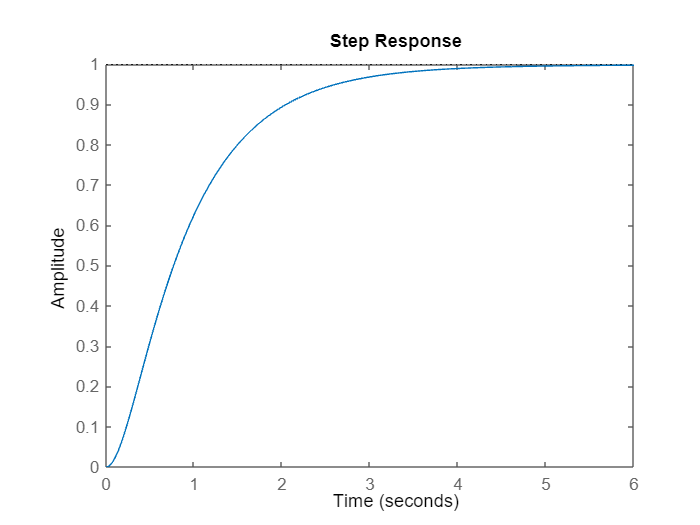

step(Ts)

stepinfo(Ts)

ans = struct with fields:
         RiseTime: 1.8171
    TransientTime: 3.4229
     SettlingTime: 3.4229
      SettlingMin: 0.9001
      SettlingMax: 0.9971
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9971
         PeakTime: 6.0839
